train_set = readmatrix("Lab5_training.txt");
test_set = readmatrix("Lab5_testing.txt");

% train sets
X_train = train_set(:, 1:4);
y_train = train_set(:, 5:7);
% test sets
X_test = test_set(:, 1:4);
y_test = test_set(:, 5:7);


net1 = get_net(X_train, y_train, 14, 'logsig', 'logsig', 100, 'trainoss');
y_pred= net1(X_test')';
y_pred_max = convert_to_max(y_pred)

y_pred_max =      1     1     1
     1     1     1
     1     1     1
     1     1     1
     1     1     1
     1     1     1
     1     1     1
     1     1     1
     1     1     1
     1     1     1


output_accuracy(y_test, y_pred)

ans = 0

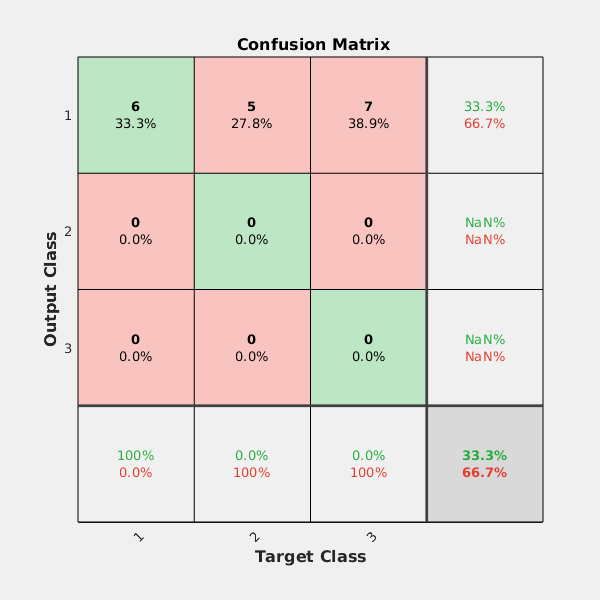

plotconfusion(y_test', y_pred_max')

output_accuracy(y_test, y_pred)

ans = 0

net1 = get_net(X_train, y_train, 10, 'logsig', 'hardlim', 10, 'traingdx');
y_pred= net1(X_test')';
y_pred_max = convert_to_max(y_pred)

y_pred_max =      1     0     0
     1     0     1
     1     0     0
     1     0     0
     1     0     0
     1     0     1
     1     0     0
     1     0     0
     1     0     1
     1     0     1


output_accuracy(y_test, y_pred)

ans = 0

plotconfusion(y_test', y_pred_max')